依赖[统一实验分析作图v19.1.0](https://github.com/ShanghaitechGuanjisongLab/Unified-Experimental-Analysis-and-Figuring/releases/)

将细胞分成学习组和自发组，看初始命中错失和学会后钙信号

GroupNtats=TransferLearning.QueryNTATS('Fig1H',TransferLearning.Flags.Different_cells_stripped);

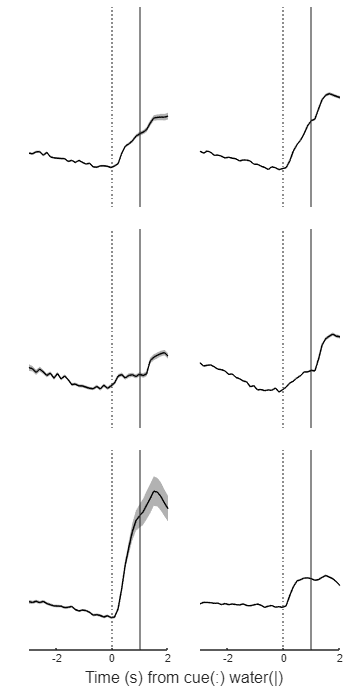

PeakValue=max(GroupNtats.NTATS,[],2);
Logical=PeakValue.Learned==max(PeakValue.Data,[],3);
[LnMean,LnSem]=MATLAB.DataFun.MeanSem(GroupNtats.NTATS{Logical,:,["Naive_hit","Naive_miss","Learned"]},1);
LnMean=permute(LnMean,[2,3,1]);
LnSem=permute(LnSem,[2,3,1]);
[SpMean,SpSem]=MATLAB.DataFun.MeanSem(GroupNtats.NTATS{~Logical,:,["Naive_hit","Naive_miss","Learned"]},1);
SpMean=permute(SpMean,[2,3,1]);
SpSem=permute(SpSem,[2,3,1]);
Fig=figure;
Layout=tiledlayout(3,2,TileSpacing='tight',Padding='tight');
Xs=linspace(-3,2,40).';
Axes=gobjects(3,2);
for T=1:3
	Axes(T,1)=nexttile;
	MATLAB.Graphics.MultiShadowedLines(LnMean(:,T),LnSem(:,T),0.3,X=Xs,EdgeColors=[0,0,0]);
	Axes(T,2)=nexttile;
	MATLAB.Graphics.MultiShadowedLines(SpMean(:,T),SpSem(:,T),0.3,X=Xs,EdgeColors=[0,0,0]);
end
for A=Axes(1:6)
	xline(A,0,':');
	xline(A,1,'-');
	A.YAxis.Visible='off';
end
Axes(1,1).XAxis.Visible='off';
Axes(2,1).XAxis.Visible='off';
Axes(1,2).XAxis.Visible='off';
Axes(2,2).XAxis.Visible='off';
MATLAB.Graphics.UnifyAxesLims(Axes);
xlabel(Layout,'Time (s) from cue(:) water(|)');
MATLAB.Graphics.FigureAspectRatio(1,2,1);
print(Fig,TransferLearning.ProjectPath('Fig1H.svg'),'-dsvg');